# Setup

clc
clear
warning('off')

%Input signals

%Position Input
N_temp = 534; %TODO: Increase time to match Land (issues with stitching chirp)
delta_t = 0.01;
t = 0:delta_t:2*N_temp*delta_t;
NT = 2*N_temp;
t1 = 0:delta_t:N_temp*delta_t;
I_p(1:N_temp+1) = 1-chirp(t1,0.5,N_temp*delta_t,1);
I_p(N_temp+1:2*N_temp+1) = 1-chirp(t1,1,N_temp*delta_t,3);

%Velocity Input
I_v = diff(I_p)/delta_t;

%Time Alignment
I_p = I_p(1:NT);
t = t(1:NT);

%Concatenate Time Series
P_in = [t;I_p]';
V_in = [t;I_v]';



# "D" Model

%Model "d"
%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'd';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
PSM = 11;
VSM = 0.6;

%Delay and zero-order hold time
delay = 0.1;

%Simulate
out = sim('d.slx');

%Outputs
d_pout = P_out;
d_vout = V_out;

%Position Error
d_error = abs(d_pout-P_in(:,2));

# Reformatted Model (just a rearrangement)

%Reformatted model
%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'SmoothModel';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
PSM = 11;
VSM = 0.6;

%Delay and zero-order hold time
delay = 0.1;

%Simulate
out = sim('SmoothModel.slx');

%Outputs
reformat_pout = out.P_out;
reformat_vout = out.V_out;

%Position Error
reformat_error = abs(reformat_pout-P_in(:,2));

# Reformatted Model with TF instead of Controller

%Reformatted model TF
%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'SmoothModelTF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
K_P = 11;
K_D = 0.6;

%Delay and zero-order hold time
delay = 0.1;

%Simulate
out = sim('SmoothModelTF.slx');

%Outputs
rtf_pout = out.P_out;
rtf_vout = out.V_out;

%Position Error
rtf_error = abs(rtf_pout-P_in(:,2));

# Reformatted TF Model with Pade Delay Approximation

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'SmoothModelTFPade';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
K_P = 11;
K_D = 0.6;

%Delay and zero-order hold time
d = 0.1;

%Pade Approximation
s = tf('s');
sys = exp(-d*s);
delayPade = pade(sys,2);

%Simulate
out = sim('SmoothModelTFPade.slx');

Found algebraic loop containing: 
SmoothModelTFPade/Transfer Fcn
SmoothModelTFPade/LTI System/Internal
SmoothModelTFPade/Sum2 (algebraic variable)



%Outputs
rtfp_pout = out.P_out;
rtfp_vout = out.V_out;

%Position Error
rtfp_error = abs(rtfp_pout-P_in(:,2));

# Pure TF model (no simulink)

%Gains
K_P = 11;
K_D = 0.6;

%Delay and zero-order hold time
d = 0.1;

%PD System w/ integrator (position)
PD = tf([K_D K_P],[1 0]);

%Pade Approximation
s = tf('s');
sys = exp(-d*s);
delayPade = pade(sys,2);

%G(s)
G = PD*delayPade;

%Feedback
TF = G/(1+G)

TF =
 
                                                      
  0.6 s^6 + 11 s^5 - 720 s^4 - 13200 s^3 + 864000 s^2 
                                                      
                                         + 1.584e07 s 
                                                      
  ----------------------------------------------------
                                                     
  1.6 s^6 + 131 s^5 + 5280 s^4 + 130800 s^3          
                                                     
                          + 2.304e06 s^2 + 1.584e07 s
                                                     
 
Continuous-time transfer function.




%Simulate

%Outputs
tf_pout = lsim(TF,I_p,t);

%Position Error
tf_error = abs(tf_pout-I_p');

# Pure Delay (no Pade approximation)

%Gains
K_P = 11;
K_D = 0.6;

%Delay and zero-order hold time
d = 0.1;

%PD System w/ integrator (position)
PD = tf([K_D K_P],[1 0]);

%Pade Approximation
s = tf('s');
sys = exp(-d*s);

%G(s)
G = PD*sys;

%Feedback
TF = G/(1+G)

TF =
 
  A = 
           x1      x2
   x1       0  -6.875
   x2       0  -6.875
 
  B = 
        u1
   x1  2.5
   x2  2.5
 
  C = 
           x1      x2
   y1    2.75  -1.031
 
  D = 
          u1
   y1  0.375
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.1  0.1 
 
Continuous-time state-space model.




%Simulate

%Outputs
tfp_pout = lsim(TF,I_p,t);

%Position Error
tfp_error = abs(tf_pout-I_p');

# Plot Original Simulink vs. Pade Approx TF

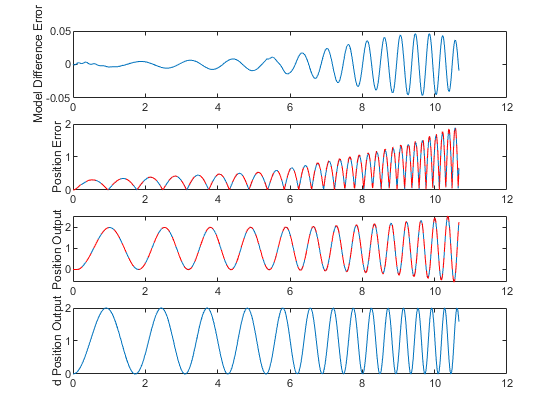

figure
subplot(4,1,1)
plot(t,d_pout-tf_pout)
ylabel('Model Difference Error')
subplot(4,1,2)
plot(t,d_error,t,tf_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,d_pout,t,tf_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

# Plot Original Simulink vs. Pure Delay SS

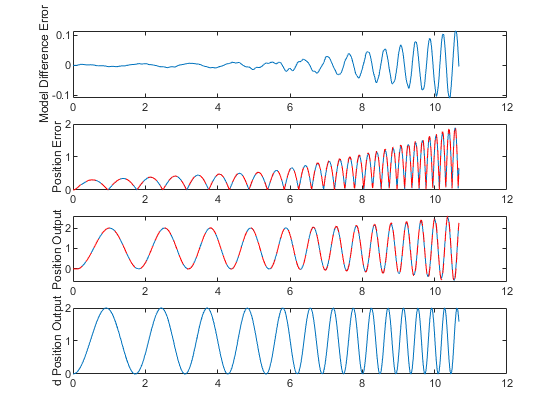

figure
subplot(4,1,1)
plot(t,d_pout-tfp_pout)
ylabel('Model Difference Error')
subplot(4,1,2)
plot(t,d_error,t,tfp_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,d_pout,t,tfp_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

# Plot Pade TF vs. Pure Delay SS

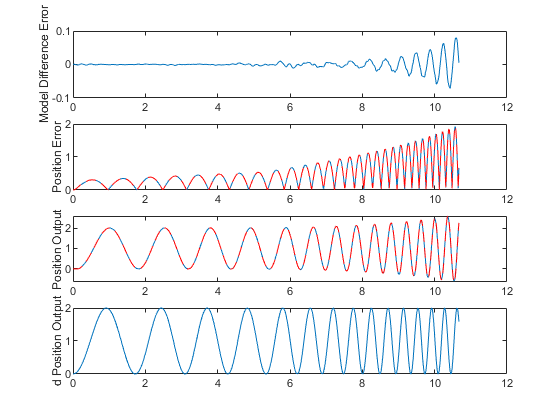

figure
subplot(4,1,1)
plot(t,tf_pout-tfp_pout)
ylabel('Model Difference Error')
subplot(4,1,2)
plot(t,tf_error,t,tfp_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,tf_pout,t,tfp_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

# Try as a Discrete Model TF

%Gains
K_P = 11;
K_D = 0.6;

%Delay time
d = 0.1;

%PD System w/ integrator (continuous)
PD = tf([K_D K_P],[1 0]);

%To discrete
PD_d = c2d(PD,delta_t,'foh');

%Add delay
tfz = tf('z',delta_t)

tfz =
 
  z
 
Sample time: 0.01 seconds
Discrete-time transfer function.



z_delay = tfz^(-10);
G_d = z_delay*PD_d

G_d =
 
  0.655 z - 0.545
  ---------------
    z^11 - z^10
 
Sample time: 0.01 seconds
Discrete-time transfer function.




%TF for PD feedback
TF_d = G_d/(1+G_d)

TF_d =
 
                                            
          0.655 z^12 - 1.2 z^11 + 0.545 z^10
                                            
  ---------------------------------------------------
                                                     
  z^22 - 2 z^21 + z^20 + 0.655 z^12 - 1.2 z^11       
                                                     
                                         + 0.545 z^10
                                                     
 
Sample time: 0.01 seconds
Discrete-time transfer function.




%Simulate

%Outputs
tfd_pout = lsim(TF_d,I_p,t);

%Position Error
tfd_error = abs(tfd_pout-I_p');

# Plot Pade TF vs Discrete TF

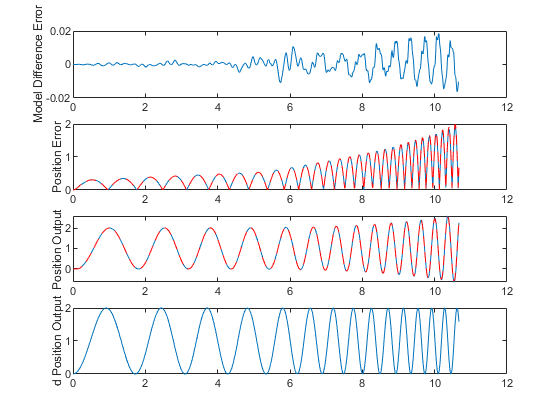

figure
subplot(4,1,1)
plot(t,tfp_pout-tfd_pout)
ylabel('Model Difference Error')
subplot(4,1,2)
plot(t,tfp_error,t,tfd_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,tfp_pout,t,tf_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')